clc;
clear;

syms x y V
d=2.5;
x=[-2*d:0.5:-d-0.5,-d-0.4:0.2:d+0.4,d+0.5:0.5:2*d];y=x';
k=8.99*10^9;
e=1.6*10^-19;
N1=1;N2=1;
q1=N1*e;q2=-N2*e;

sqrt((x-d).^2+y.^2).\(k*q1);
V=sqrt((x-d).^2+y.^2).\(k*q1)+sqrt((x+d).^2+y.^2).\(k*q2);
[Dx,Dy]=gradient(-10^10*V); 

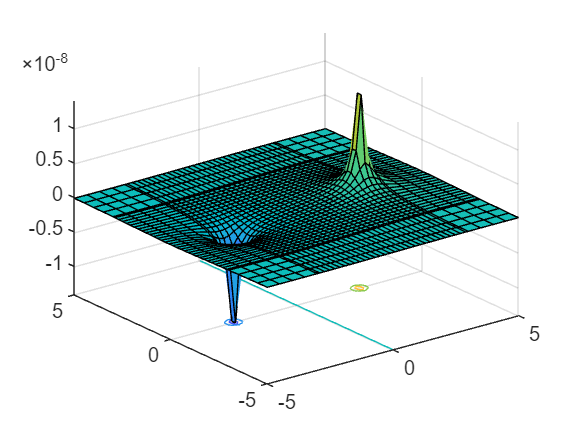

surfc(x,y,V)

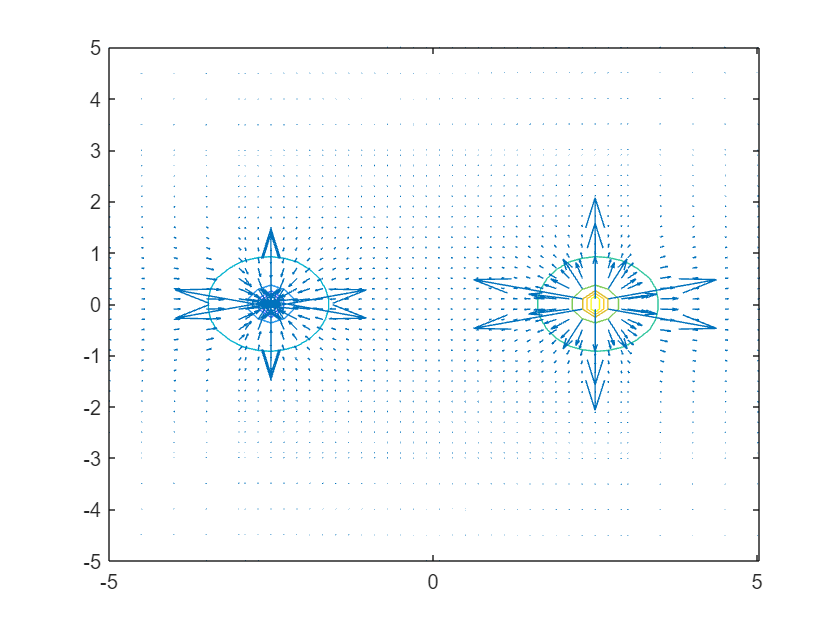

contour(x,y,V,10)
hold on
quiver(x,y,Dx,Dy,5)